# Final Assignment 5SMB0

saturated u = 2.2  @  r> | 2.3251 |

N = 100;
t = [0:0.1:400*pi]

t = 1.0e+03 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


r = t.*sin(0.09*t.*t) 

r = 1.0e+03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0011    0.0012    0.0013    0.0015    0.0016    0.0018    0.0020    0.0022    0.0024    0.0025    0.0027    0.0029    0.0031    0.0033    0.0035    0.0037    0.0038    0.0040    0.0041    0.0042    0.0043    0.0043    0.0044    0.0043    0.0043    0.0042    0.0041


mode = 'open loop';
[u,y] = assignment_sys_14(r,mode)

u =          0
    0.0001
    0.0006
    0.0020
    0.0051
    0.0101
    0.0178
    0.0287
    0.0432
    0.0619


y =     0.0006
   -0.0052
   -0.0002
    0.0106
   -0.0020
   -0.0166
    0.0061
    0.0170
   -0.0109
   -0.0124


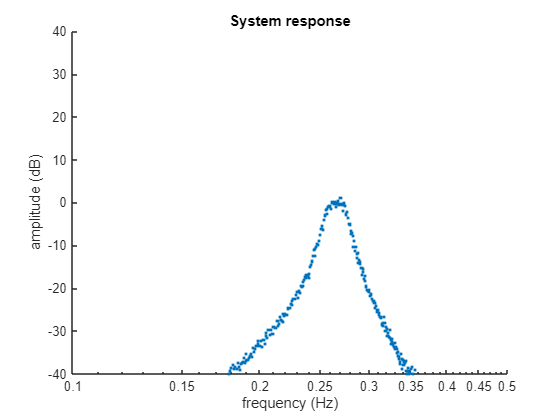

plot(y)

Zooming into the function:

t = [0:0.1:40*pi];
r = t.*sin(0.08*t.*t);
mode = 'open loop';
[u,y] = assignment_sys_14(r,mode);
plot(y)

max_out = max(abs(y))

max_out = 2.9224

Rough estimation saturation y < |3.0|

max(abs(y))

ans = 2.9224

frf = modalfrf(x,y,1,window)

Unrecognized function or variable 'x'.

butterworth: 2nd order low-pass filter, cutt_off at 2.65 rad/s, stop band edge at 3.1 rad/s, => T_f = 3,14 rad/s 

btt_num = [0.7157 1.4315 0.7157];
btt_den = [1 1.3490 0.5140];
figure;
F = tf(btt_num, btt_den, 1.0);  %, -1
bode(F);
ylim([-80 0]);
grid on;
title('Bode Plot (Magnitude and Phase)');

Quite steep frequency roll over, visualization artifact caused by the bilinear transform of the filter. 

1.1 (3 points) The (partially) known parts of the system consist of F(q) and S. Determine

by an initial experiment the parameter M and explain what influence F(q) and

S will have on the identification of the unknown part H and G. This could be, e.g., on

the remaining steps of the system identification cycle, limitations on the obtained final

model, etc.

F(q) acts as a low pass filter, with a cut-off frequency of ~ 2.65 rad/s. The filter will have the effect of reducing the possible excitation range of the system, looking at the filter stats, excitation above stop-band edge frequency range will results in supression. Given the nyquist frequency of Pi rad/s, this cut-off frequency allows to filter high-frequency noise in the discrete frequency spectrum.

Function S is limiting the maximium input amplitude, and therefore input power into the system.

Therefore it's important for the system identification to limit input power/amplitude and excite only relevant frequencies, till nyquist frequency?

2.1 (4 points) We first want to get a rough idea of the frequency behavior of G0(q). To

this end, we want to perform a preliminary experiment and apply nonparametric system

identification using the collected data. The task is then to design an experiment of length

N = 1500. What type of reference shall be used? Give an expression of r(k) and motivate

your choice.

For performing model estimation with a non-parameric approach, an experiment should be designed that excite important frequences. To avoid specral leakage effects, a fundamentel frequency f_0 will be chosen with exicted harmonics on a logarithmic scale to equally distribute power throughout frequency decades. A uniformly distributed random phase is used to ensure a good crest factor

Max nyquist frequncy is pi rad/s => 1/2*T_s

N = 1500; % number of points per period
fs = 1; % sampling frequency in Hz
Ts = 1/fs;  % sampling interval in seconds
f0 = fs/N;  % the frequency resolution in Hz
fmin = 0.05 %fs/10;     % lowest excited frequency in Hz - should be larger than 0 and smaller than fmax

fmin = 0.0500

fmax = 0.5 %fs/2 %0.35 %2*fs/5;   % highest excited frequency in Hz - should be lower than the nyquist frequency fs/2

fmax = 0.5000

F = 30;    % maximum number of excited frequencies
t = (0:1:N-1)*Ts; % time vector in sec. we start at 0, so we need to stop at N*Ts-Ts to have a total of N samples
f = (0:1:N-1)*f0; % frequency vector in Hz




nmin = ceil(fmin/f0);  % the frequency bin of the lowest excited frequency
nmax = floor(fmax/f0); % the frequency bin of the highest excited frequency
bins = nmin:nmax;
binslog = round(logspace(log10(nmin),log10(nmax),F)); % logarithmically spaced frequency rounded to closest grid point
binslog = unique(binslog(:).'); % remove frequency bin values that appear multiple times in the vector
% due to this last operation, the total number of excited frequency can be
% lower than the previously defined F.
binslin = round(linspace(nmin, nmax, length(binslog)))

binslin =     75    98   122   145   168   191   215   238   261   284   308   331   354   378   401   424   447   471   494   517   541   564   587   610   634   657   680   703   727   750


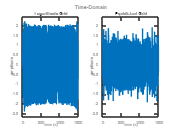


F = nmax-nmin+1;
A = zeros(1,N/2-1); A(bins+1)=1; % constant amplitude on the excited frequency bins
% phi = zeros(1,N/2-1); phi(bins+1) = -(bins+1).*(bins).*pi/F; % Schroeder phase
phi = zeros(1,N/2-1); phi(bins+1) = -(bins-nmin+1).*(bins-nmin).*pi/F; % Schroeder phase
U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
usp = real(ifft(U))*N;
usp = 1.4*usp/std(usp); % scaled to have a standard deviation = 1
Usp = fft(usp);

A = zeros(1,N/2-1); A(binslog+1)=1; % constant amplitude on the excited frequency bins
%phi = zeros(1,N/2-1); phi(binslog+1) = 2*pi*rand(1,length(binslog));
%phi = zeros(1,N/2-1); phi(binslog+1) = -(binslog-nmin+1).*(binslog-nmin)*pi/F; % Schroeder phase
phi = zeros(1,N/2-1); phi(binslog+1) = 2*pi*rand(1,length(binslog)); % random phases, uniformly distributed between 0 and 2pi
U = zeros(1,N);
U(binslog+1) = A(binslog+1).*exp(1i*phi(binslog+1));
ulg = real(ifft(U))*N;
ulg = 0.7*ulg/std(ulg); % scaled to have max abs = 2
Ulg = fft(ulg);

A = zeros(1,N/2-1); A(binslin+1)=1; % constant amplitude on the excited frequency bins
phi = zeros(1,N/2-1); phi(binslin+1) = 2*pi*rand(1,length(binslin)); % random phases, uniformly distributed between 0 and 2pi
%phi = zeros(1,N/2-1); phi(binslin+1) = -(binslin-nmin+1).*(binslin-nmin).*pi/F;
U = zeros(1,N);
U(binslin+1) = A(binslin+1).*exp(1i*phi(binslin+1));
ueq = real(ifft(U))*N;
ueq = 0.7*ueq/std(ueq); % scaled to have max abs = 2
Ueq = fft(ueq);

yl = [min([ulg,ueq]), max([ulg,ueq])];
yl = 1.1*yl;

figure; tcl = tiledlayout(1,2); title(tcl,'Time-Domain')
nexttile; plot(t,usp); xlabel('time (s)'); ylabel('amplitude'); title('Logarithmic Grid'); ylim(yl);
nexttile; plot(t,ueq); xlabel('time (s)'); ylabel('amplitude'); title('Equidistant Grid'); ylim(yl);

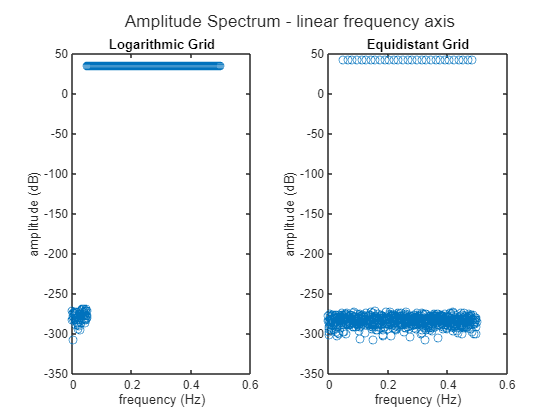

figure; tcl = tiledlayout(1,2); title(tcl,'Amplitude Spectrum - linear frequency axis')
nexttile; plot(f(1:end/2),db(Usp(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Logarithmic Grid'); yl = ylim;
nexttile; plot(f(1:end/2),db(Ueq(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Equidistant Grid'); ylim(yl);

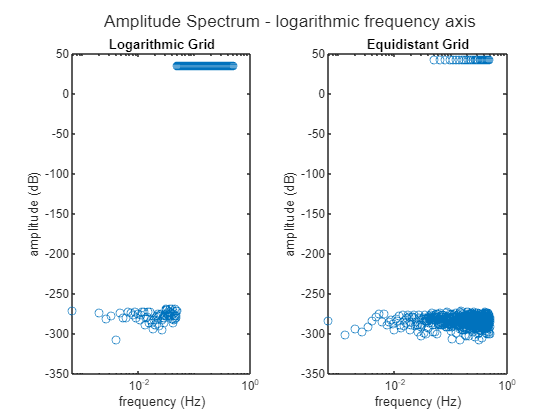

figure; tcl = tiledlayout(1,2); title(tcl,'Amplitude Spectrum - logarithmic frequency axis')
nexttile; semilogx(f(1:end/2),db(Usp(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Logarithmic Grid'); yl = ylim;
nexttile; semilogx(f(1:end/2),db(Ueq(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Equidistant Grid'); ylim(yl);

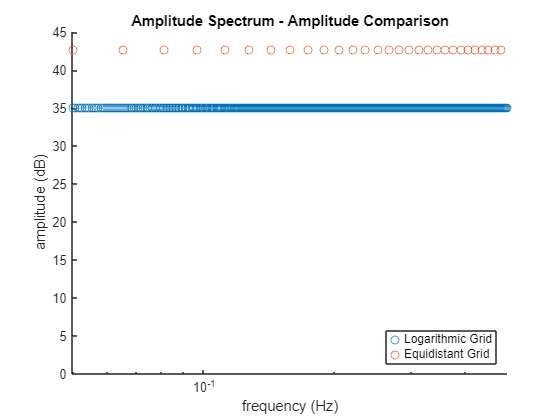

figure; hold on; title('Amplitude Spectrum - Amplitude Comparison')
semilogx(f(1:end/2),db(Usp(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)');  
semilogx(f(1:end/2),db(Ueq(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)');  
ylim([0 max(db(Usp(1:end/2)))+10]); set(gca, 'XScale', 'log'); legend('Logarithmic Grid','Equidistant Grid','Location','southeast')


Alg = max(abs(Usp)); disp(['Amplitude of excited frequencies - logarithmic grid: ' num2str(db(Alg)) ' dB'])

Amplitude of excited frequencies - logarithmic grid: 41.1459 dB


Aeq = max(abs(Ueq)); disp(['Amplitude of excited frequencies - equidistant grid: ' num2str(db(Aeq)) ' dB'])

Amplitude of excited frequencies - equidistant grid: 42.7356 dB


Generate signal output with reference signal sure bud

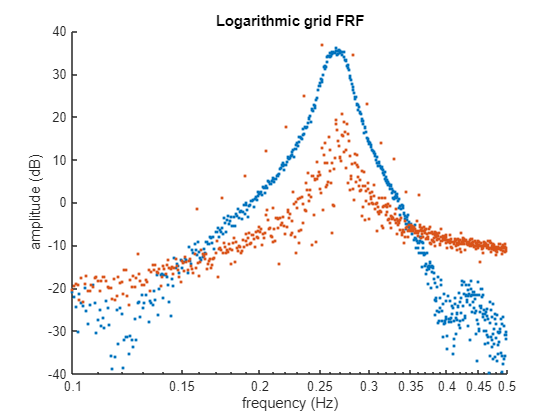

mode = 'open loop';
[u,y] = assignment_sys_14(usp,mode);
Y = fft(y);
[u,y_e] = assignment_sys_14(ueq,mode);
Y_e = fft(y_e);

figure;
hold on; xscale('log'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Logarithmic grid FRF'); xlim([0.1, 0.5]); ylim([-40, 40]);
plot(f(1:end/2),db(Y(1:end/2)),'.'); 
plot(f(1:end/2),db(Y_e(1:end/2)),'.');

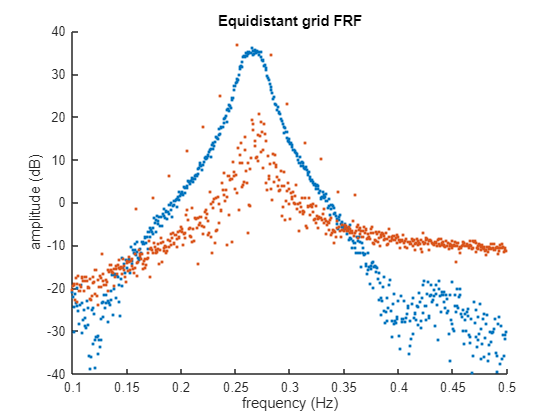


figure; hold on; xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Equidistant grid FRF'); xlim([0.1, 0.5]); ylim([-40, 40]); 
plot(f(1:end/2),db(Y(1:end/2)),'.'); 
plot(f(1:end/2),db(Y_e(1:end/2)),'.'); 

emperical transfer function fit FRF : emprical transfer function estimation 

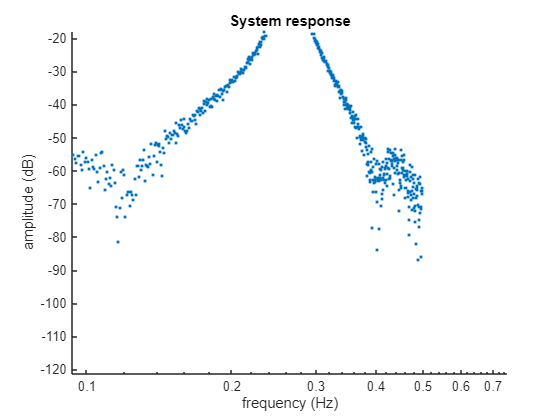

G_0 = Y ./ Usp';
figure; hold on; xscale('log'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('System response'); xlim([0.1, 0.5]); ylim([-40, 40]); 
plot(f(1:end/2),db(G_0(1:end/2)),'.'); 

final FRF Aproach: Schroeder + fixed frequency portion , averaged over samples

G = complex(zeros(1, N))

G =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


for i = 1:1000
    [u,y] = assignment_sys_14(usp,mode);
    Y = fft(y);
    G(i, :) = Y ./ Usp';
end
G_average = 1.0/1000.0 * sum(G, 1)

G_average = 1.0e+12 *

  -0.1328 + 0.0000i   0.0317 + 0.0064i      NaN +    NaNi  -0.0291 - 0.0197i   0.0012 - 0.0451i   0.0065 - 0.0493i  -2.1016 - 1.5314i  -0.0230 - 0.0080i  -0.1068 + 0.0065i   0.0596 + 0.0163i  -0.0394 + 0.0435i   0.0318 - 0.0113i   0.0037 + 0.0363i   0.0069 + 0.0266i  -0.0275 - 0.0162i   0.0486 - 0.0044i  -0.0453 - 0.0565i   0.0304 + 0.0641i   0.0049 - 0.0083i   0.0212 - 0.0371i  -0.2130 - 0.0152i  -0.0591 - 0.0681i  -0.0384 - 0.0481i   0.0092 - 0.0371i   0.2046 + 0.0090i   0.0359 - 0.0299i  -0.1043 + 0.0367i  -0.1367 + 0.0997i  -0.2408 - 0.0158i  -0.0522 + 0.1143i  -0.1716 + 0.2174i   0.0657 + 0.0308i  -0.0720 - 0.0151i   0.0010 + 0.0769i  -0.0610 + 0.0631i   0.1257 - 0.0113i  -0.3962 + 0.1234i   0.0087 + 0.0710i  -0.0496 + 0.0604i   0.0315 + 0.1024i   0.0197 - 1.0632i  -0.0657 + 0.2640i  -0.0505 - 0.0411i  -0.0042 + 0.0058i   0.1576 + 0.1677i  -0.0413 + 0.0061i   0.0142 - 0.0081i   0.0075 - 0.0138i   0.0112 + 0.0090i   0.0032 + 0.0429i


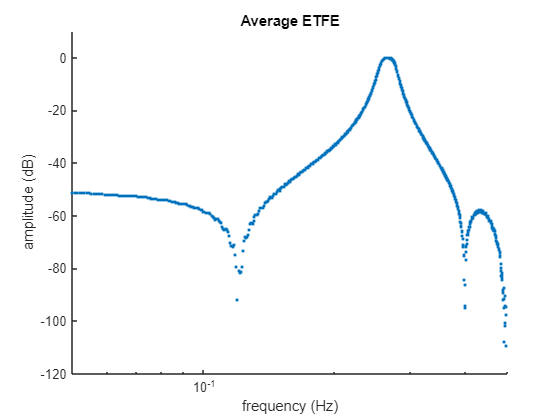

figure; hold on; xscale('log'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Average ETFE'); xlim([0.05, 0.5]); ylim([-120, 10]); 
plot(f(1:end/2),db(G_average(1:end/2)),'.'); 

observations 2.2:

- Small resonance at ~0.27 Hz

- high-frequency charcterized by second peak at ~0.43 Hz

- Gain is mostly negative as illustrated by negative gain. 

G_average_noise_pwr = var(G, 1)

G_average_noise_pwr = 1.0e+27 *

    0.0145    0.0009       NaN    0.0014    0.0093    0.0041    3.6171    0.0016    0.0070    0.0080    0.0014    0.0019    0.0030    0.0012    0.0068    0.0026    0.0115    0.0032    0.0011    0.0011    0.0597    0.0077    0.0058    0.0011    0.0297    0.0011    0.0116    0.0267    0.1903    0.0116    0.0572    0.0063    0.0111    0.0046    0.0023    0.0035    0.0668    0.0025    0.0025    0.0022    0.2407    0.0123    0.0070    0.0078    0.0311    0.0043    0.0035    0.0007    0.0005    0.0008


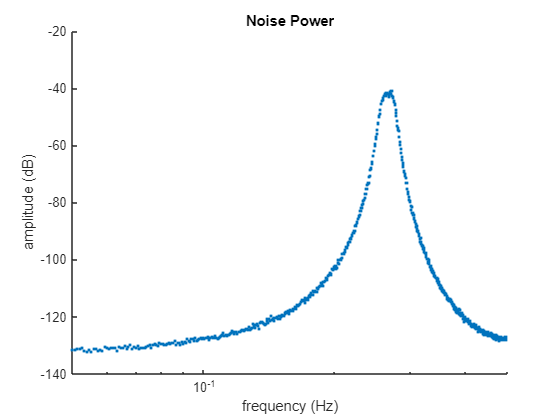

figure; hold on; xscale('log'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Noise Power'); xlim([0.05, 0.5]); ylim([-140, -20]); 
plot(f(1:end/2),db(G_average_noise_pwr(1:end/2)),'.'); 

Parametric approach: 

N = 1500

N = 1500

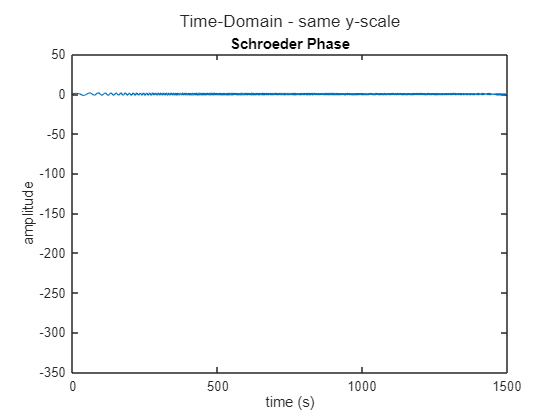

Ts = 1/fs;  % sampling interval in seconds
f0 = fs/N;  % the frequency resolution in Hz
fmin = 0.01; % lowest excited frequency in Hz - should be larger than 0 and smaller than fmax
fmax = 0.5;   % highest excited frequency in Hz - should be lower than the nyquist frequency fs/2

t = (0:1:N-1)*Ts; % time vector in sec. we start at 0, so we need to stop at N*Ts-Ts to have a total of N samples
f = (0:1:N-1)*f0; % frequency vector in Hz

nmin = ceil(fmin/f0);  % the frequency bin of the lowest excited frequency
nmax = floor(fmax/f0); % the frequency bin of the highest excited frequency
bins = nmin:nmax; % vector containing the excited frequency bins
F = nmax-nmin+1;
A = zeros(1,N/2-1); A(bins+1)=1; % constant amplitude on the excited frequency bins
% phi = zeros(1,N/2-1); phi(bins+1) = -(bins+1).*(bins).*pi/F; % Schroeder phase
phi = zeros(1,N/2-1); phi(bins+1) = -(bins-nmin+1).*(bins-nmin).*pi/F; % Schroeder phase
U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));
usp = real(ifft(U))*N;
usp = usp/std(usp); % scaled to have a standard deviation = 1
Usp = fft(usp);


figure; tcl = tiledlayout(1,1); title(tcl,'Time-Domain - same y-scale')
nexttile; plot(t,usp); xlabel('time (s)'); ylabel('amplitude'); title('Schroeder Phase'); ylim(yl);  

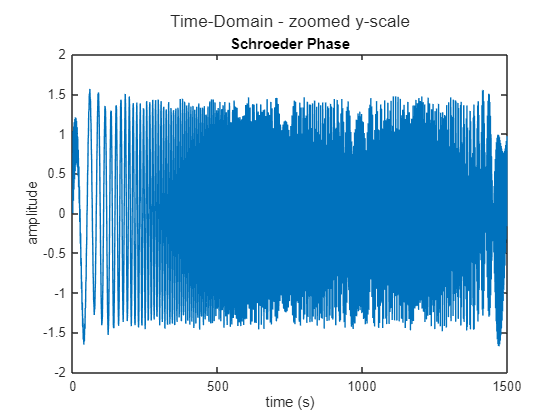


figure; tcl = tiledlayout(1,1); title(tcl,'Time-Domain - zoomed y-scale')
nexttile; plot(t,usp); xlabel('time (s)'); ylabel('amplitude'); title('Schroeder Phase'); 

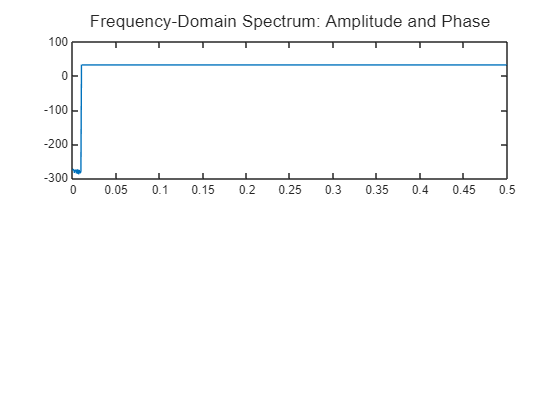


figure; tcl = tiledlayout(2,1); title(tcl,'Frequency-Domain Spectrum: Amplitude and Phase');
nexttile; plot(f(1:end/2),db(Usp(1:end/2)));

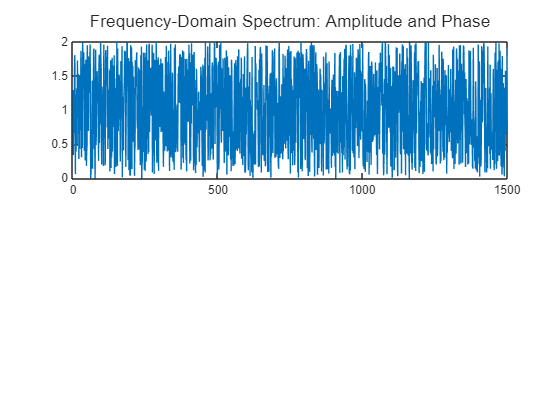

mode = 'open loop';
urand = 2*rand(1,length(ueq));
plot(urand);

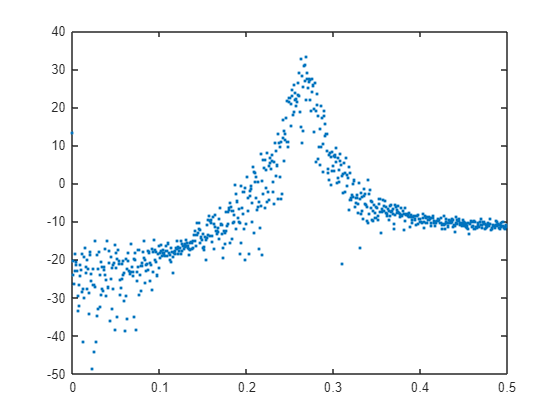

[u_est,y_est] = assignment_sys_14(urand,mode);
Y_est = fft(y_est);

figure; xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Equidistant grid FRF'); %xlim([0.1, 0.5]); ylim([-40, 40]); 
plot(f(1:end/2),db(Y_est(1:end/2)),'.'); 

ute = urand

ute =     1.2929    0.3404    0.9735    0.8994    0.6606    1.7501    1.8014    0.7594    0.0632    1.2084    0.3932    0.8718    1.3146    1.1000    0.5013    1.7234    1.0568    0.8777    1.5282    1.1673    0.2830    1.0379    1.5122    0.4314    1.3004    0.7085    0.6981    1.8638    1.5367    0.3092    0.9960    1.1932    0.4446    1.9901    1.7329    1.7163    1.8424    1.8339    1.0962    0.4048    1.6669    1.2168    0.2638    0.8133    1.7361    1.4130    0.1837    0.4016    0.4811    1.9470


yte = y_est

yte =     0.0084
    0.0018
   -0.0160
    0.0047
    0.0307
   -0.0046
   -0.0224
    0.0202
    0.0138
   -0.0137


data_train = iddata(yte, ute', Ts);
opt = armaxOptions('Focus','simulation'); 
myarma = armax(ute', yte,[4 6 4 0], opt)


myarma =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                                       
  A(z) = 1 + 0.3672 z^-1 + 1.852 z^-2 + 0.3341 z^-3 + 0.8341 z^-4                               
                                                                                                
  B(z) = 0.007357 + 0.004751 z^-1 - 0.001427 z^-2 - 0.00145 z^-3 + 0.005961 z^-4 - 0.001605 z^-5
                                                                                                
  C(z) = 1 + 0.07432 z^-1 + 0.3862 z^-2 - 0.1168 z^-3 + 0.03551 z^-4                            
                                                                                                
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=6   nc=4   nk=0
   Number of free coefficients: 14
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using ARMAX on time domain data.      
Fit 

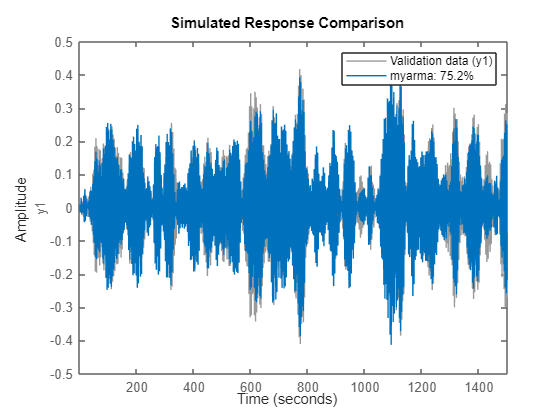

compare(data_train, myarma, compareOptions('InitialCondition','z'))

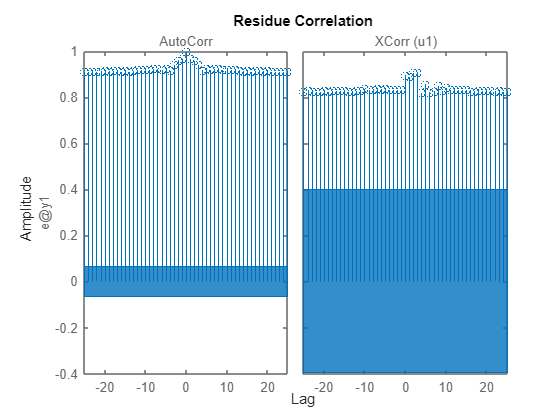

% data_test = iddata(y_est, usp', Ts); 

% sys = armax(data_train,[3 4 3 1])
% opt = compareOptions('InitialCondition','estimate'); 
% [y,Fit] = compare(data_train,sys,opt)

urand2 = 2*rand(1,length(ueq));
y_test = assignment_sys_14(urand2,mode);  % lsim(arma, urand');
data_test = iddata(y_test, urand2', Ts);
arma_y = lsim(myarma, urand2');
arma_Y = fft(arma_y);
bode(myarma);
% figure; hold on;
% plot(y_est);
% plot(arma_y)
% 
% 
% compare(data_test, arma);
resid(data_test, myarma);

na = 1:12; nb = 3:8; nc = 1:5; nk = 0:2;
best_fit = inf;
best_order = [];

for i = na
    for j = nb
        for k = nc
            for l = nk
                sys = armax(ute', yte,[i j k l], opt);
                if sys.Report.Fit.FPE < best_fit
                    best_fit = sys.Report.Fit.FPE;
                    best_order = [i j k l];
                end
            end
        end
    end
end


y_arma = lsim(arma, usp');

Unrecognized function or variable 'arma'.

var_arma = var(y_arma, 1)
VAR_arma = fft(var_arma)
Y_arma = fft(y_arma); 
figure; hold on; xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('arma response'); %xlim([0.05, 0.5]); ylim([-120, 10]); 
plot(f(1:end/2),db(Y_arma(1:end/2)),'.'); 
figure; hold on; xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('arma variance'); %xlim([0.05, 0.5]); ylim([-120, 10]); 
plot(f(1:end/2),db(VAR_arma(1:end/2)),'.'); 